clear; close all; clc;

filename = 'ref_a0.6'

filename = 'ref_a0.6'

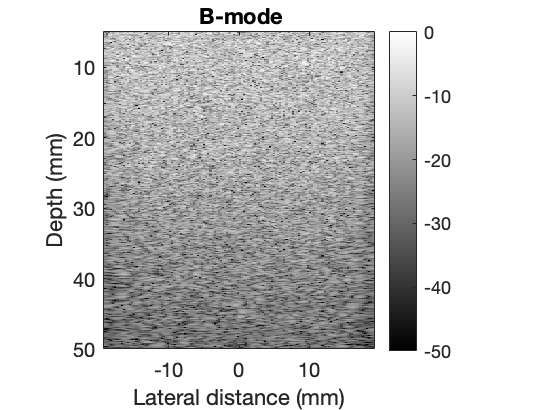

load('ref.mat')


plot_bmode(rf,x,z)


b = 1e-2;
n = 1.5;


rfbsc = add_bsc(rf, b, n, fs)

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



rfbsc =     0.0464    0.0111   -0.1421   -0.0364    0.0060   -0.0015   -0.0237    0.0229   -0.0004   -0.0928   -0.0154   -0.0211   -0.0478    0.0468    0.0006   -0.0393    0.0356    0.0369    0.0361   -0.0131   -0.0290    0.0121    0.0251   -0.0233    0.0333    0.0237   -0.0386   -0.0030    0.0258    0.0337   -0.0665   -0.0346   -0.0127   -0.0168   -0.0479   -0.0371    0.0028    0.0384    0.0461    0.0203    0.0374   -0.0342   -0.0430    0.0059    0.0440    0.0411    0.0602    0.0593   -0.0085   -0.0488
    0.0299    0.0077   -0.0653   -0.0234    0.0020   -0.0048   -0.0059    0.0248    0.0058   -0.0450   -0.0029   -0.0184   -0.0234    0.0199    0.0003   -0.0307    0.0131    0.0106    0.0266   -0.0082   -0.0093    0.0045    0.0149   -0.0112    0.0055    0.0119   -0.0126   -0.0034    0.0052    0.0164   -0.0109   -0.0123   -0.0104   -0.0031   -0.0226   -0.0177    0.0096    0.0158    0.0188    0.0122    0.0197   -0.0114   -0.0116    0.0056    0.0199    0.0185    0.0344    0.0370   -0.0065 

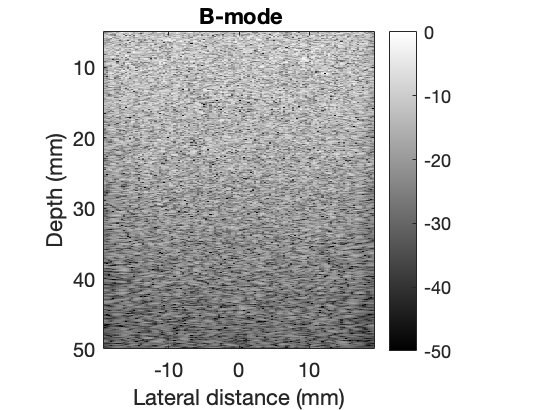


%keyboard

c = 1540; dt = 1/fs;
zbsc = c*(1:length(rfbsc))*dt/2;
plot_bmode(rfbsc, x, zbsc )


znew = zbsc(1:length(z));
rfnew = rfbsc(1:length(z),:);
xnew = x;


keyboard
x = xnew;
z = znew;
rf = rfnew;
save([filename,'b',num2str(b),'n',num2str(n),'.mat'],'xnew','znew','rfnew');


keyboard



## Function to add bf^n

function [rfoutput] = add_bsc(rfinput, b, n, fs)

N = size(rfinput,2);

for ii = 1:N

    disp(ii)
    rf = rfinput(:,ii);

    %figure; plot(rf);

    NFFT = 2^15;
    freq = (-NFFT/2:NFFT/2-1)/NFFT*fs*1e-6;

    ps = power(abs(fftshift(fft(rf,NFFT))),2);

    ps_new = ps.*(b*abs(freq').^n);
    ps_new = ps_new/max(ps_new);

    newfft = fftshift(fft(rf,NFFT)) .* sqrt(b*abs(freq').^n);
    newps = power( abs(newfft),2 );

    newrf = ifft(fftshift(newfft),NFFT);

    rfoutput(:,ii) = newrf;


    continue
    figure; plot(freq,20*log10(ps/max(ps))); hold on;
    plot(freq, 10*log10(ps_new) );
    plot(freq,10*log10(b*abs(freq').^n))
    plot(freq,10*log10(newps./max(newps)))

   
    figure;
    plot(rf); hold on;
    plot(newrf);
    %keyboard



    keyboard

end


%keyboard

end




## **Function B-mode plot**

function [] = plot_bmode(rf,x,z,varargin)


%disp(nargin)

rf = rf(:,:,1);

[~,idxL] = min(abs(z - 5e-3));
[~,idxH] = min(abs(z - 50e-3));
z = z(idxL:idxH)';
rf = rf(idxL:idxH,:);

rfenv = abs(hilbert(rf));
rfenv = rfenv./max(rfenv(:));

%x = 0.3e-3*(1:size(rf,2)); x = x-mean(x);
%figure(figN);

figure;
imagesc(x*1e3,z*1e3,20*log10(rfenv));
colormap gray; axis image
clim([-50 0]);

%font = 20;
%set(gca,'fontsize',font)
ylabel('Depth (mm)');
xlabel('Lateral distance (mm)');
if nargin > 3
    title(varargin{1});
else
    title("\bf B-mode");
end
%set(gca,'FontSize',font);
colorbar

end